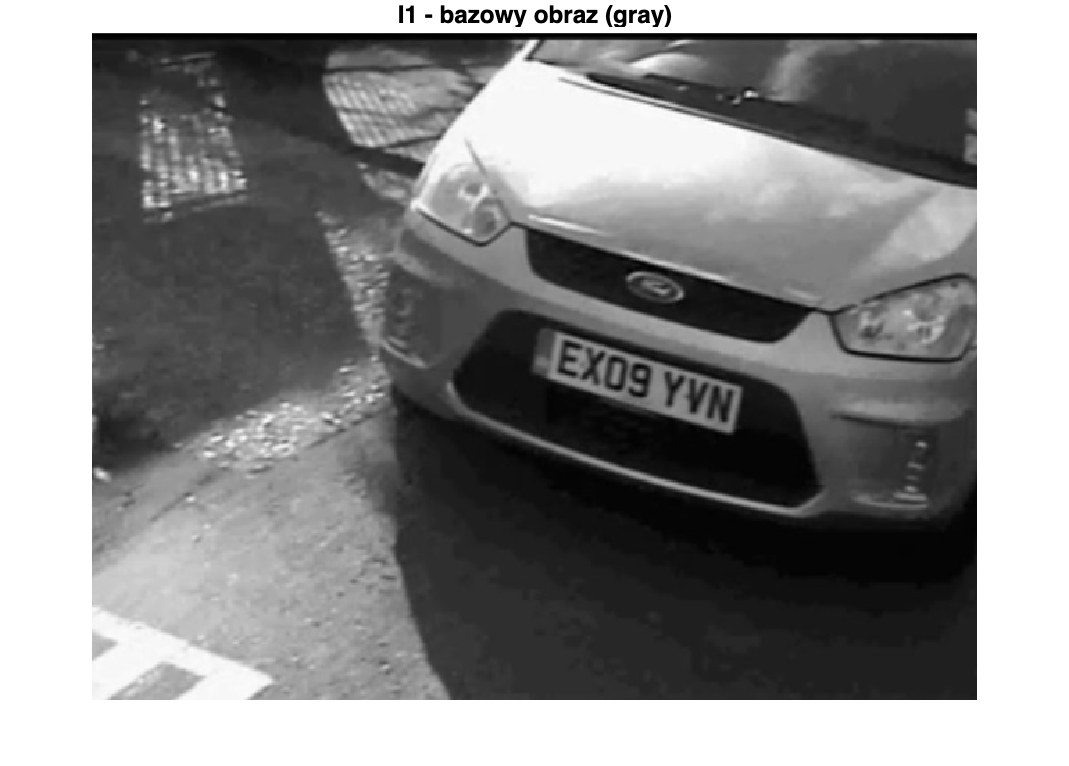

close all; clear all; clc

% 1. Wczytanie obrazu
I = imread('car1.jpg');  % lub car2.jpg
I1 = double(rgb2gray(I)); % przejście do skali szarości
figure; imshow(I1, []); title('I1 - bazowy obraz (gray)');

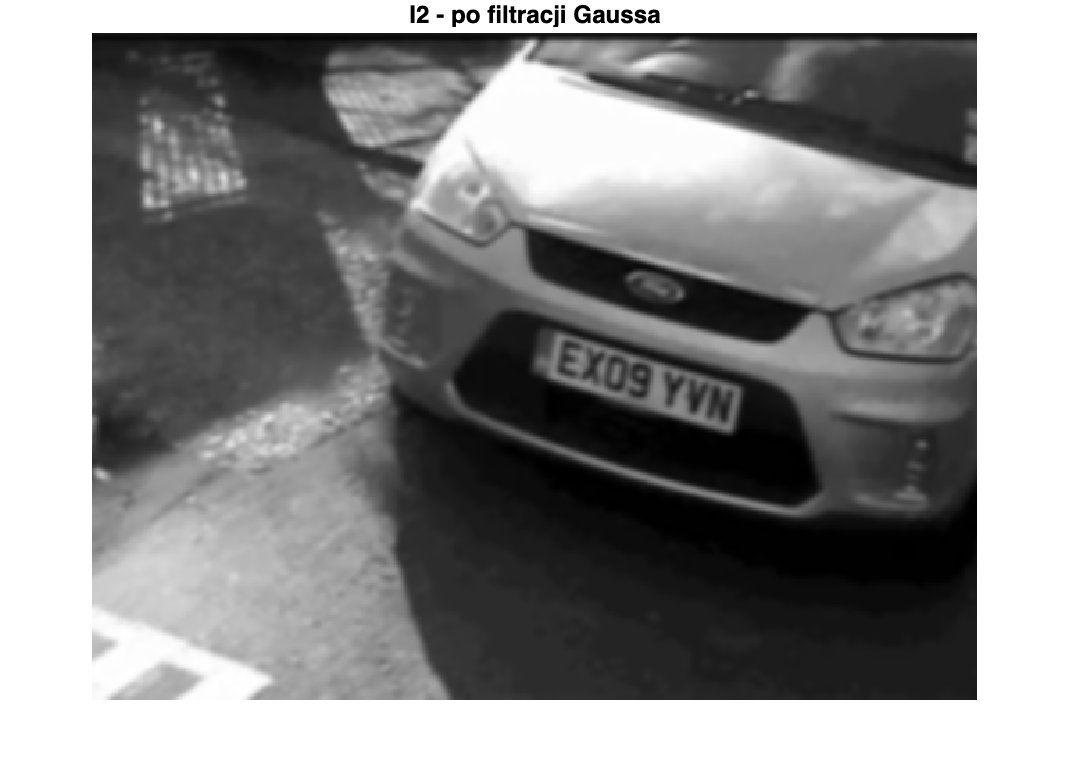


% 2. Filtracja dolnoprzepustowa - filtr Gaussa
h = fspecial('gaussian', [7 7], 2);  % maska 7x7, sigma = 2
I2 = imfilter(I1, h, 'replicate'); % filtracja
figure; imshow(I2, []); title('I2 - po filtracji Gaussa');

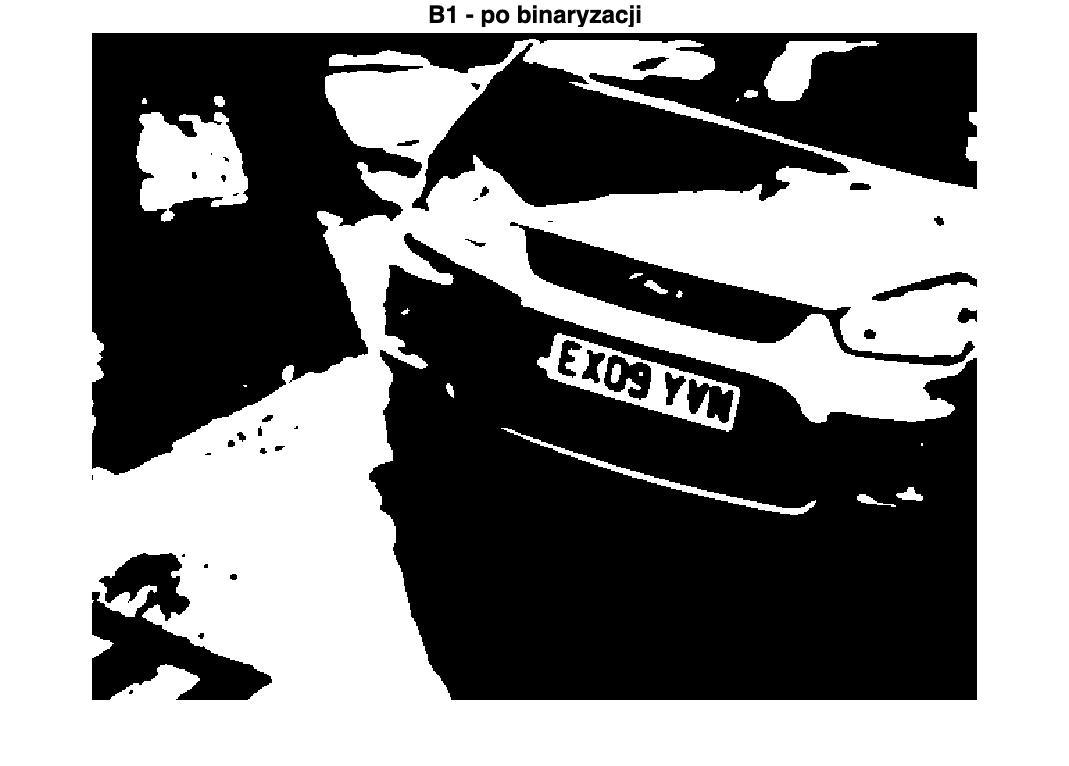


% 3. Kwantyzacja
I2 = round(I2); % zaokrąglenie do przedziału 0-255
I2 = uint8(I2); % konwersja do typu uint8

% 4. Dobór progu - interaktywnie (skomentuj po ustaleniu)
% imcontrast(imshow(I2)) % pozwala dobrać lt, ut ręcznie

lt = 90;  % dolny próg binaryzacji (dostosuj ręcznie po użyciu imcontrast)
ut = 200;  % górny próg binaryzacji

% 5. Binaryzacja
B1 = I2;
B1(B1 < lt) = 0;
B1(B1 > ut) = 0;
B1(B1 > 0) = 1;
figure; imshow(B1, []); title('B1 - po binaryzacji');

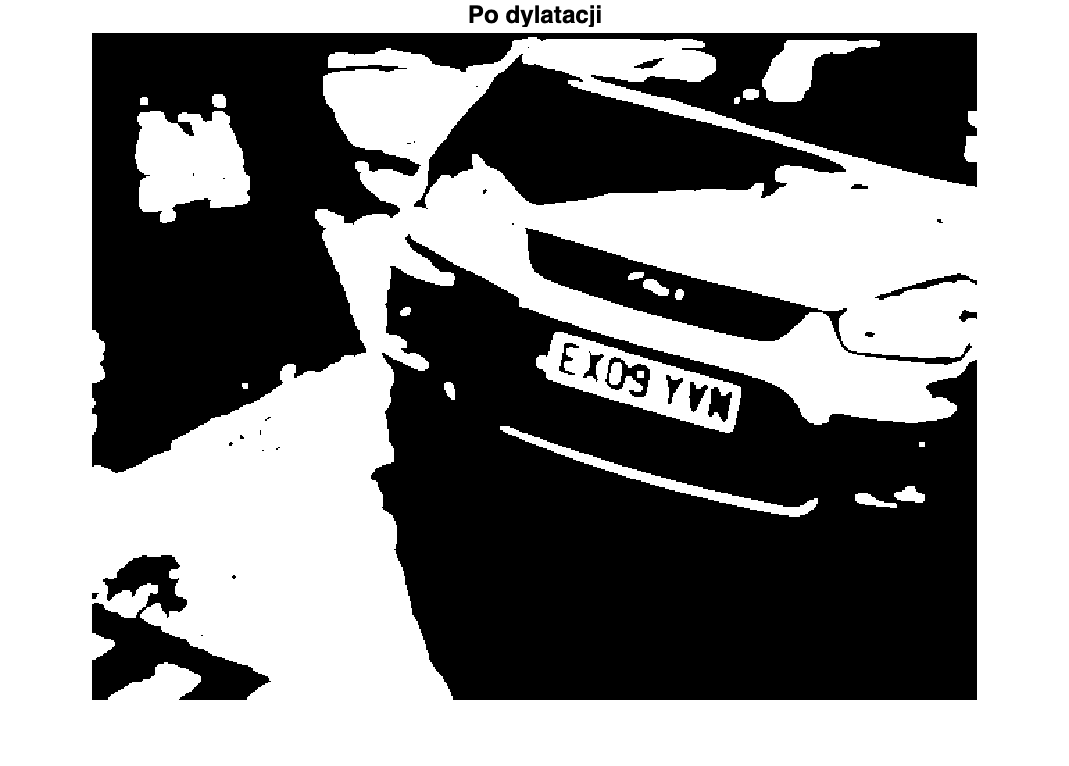


% 6. Operacje morfologiczne
B1 = bwmorph(B1, 'dilate', 1); % dylatacja (2 iteracje) -> powiękasz białe obsazary, wypełnia szczeliny, łączy obiekty
figure; imshow(B1, []); title('Po dylatacji');

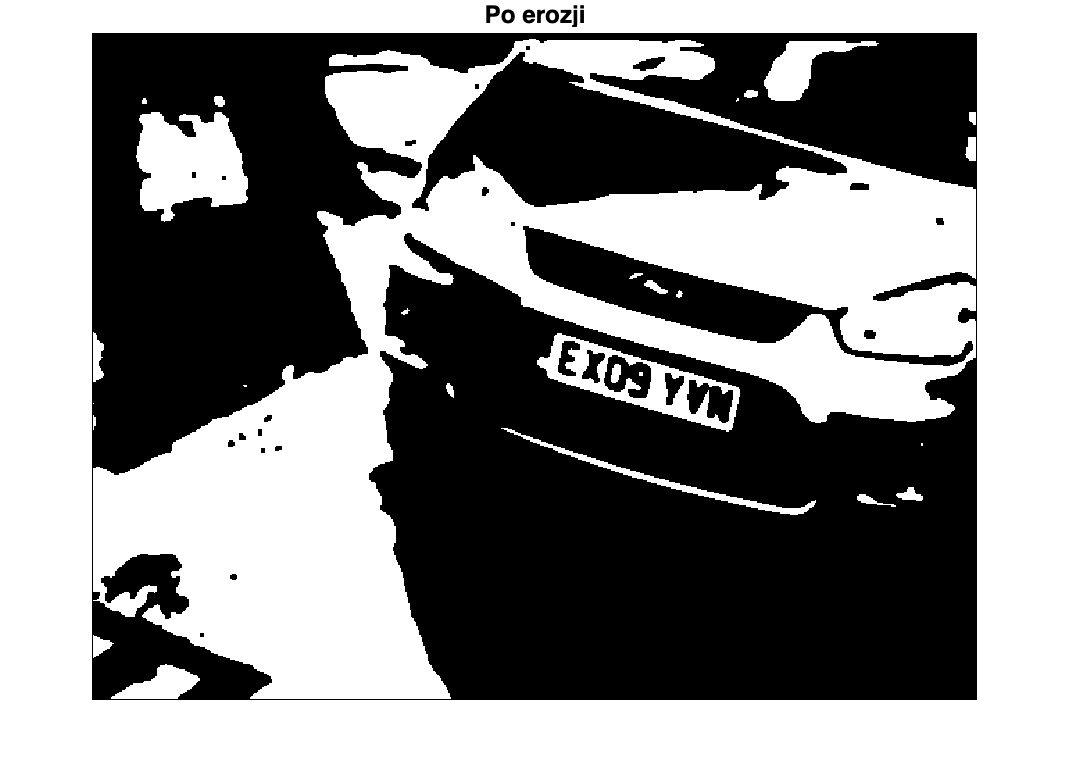


B1 = bwmorph(B1, 'erode', 1); % erozja (1 iteracja) -> zmniejsza obszary, usuwa cienkie struktury i szumy
figure; imshow(B1, []); title('Po erozji');

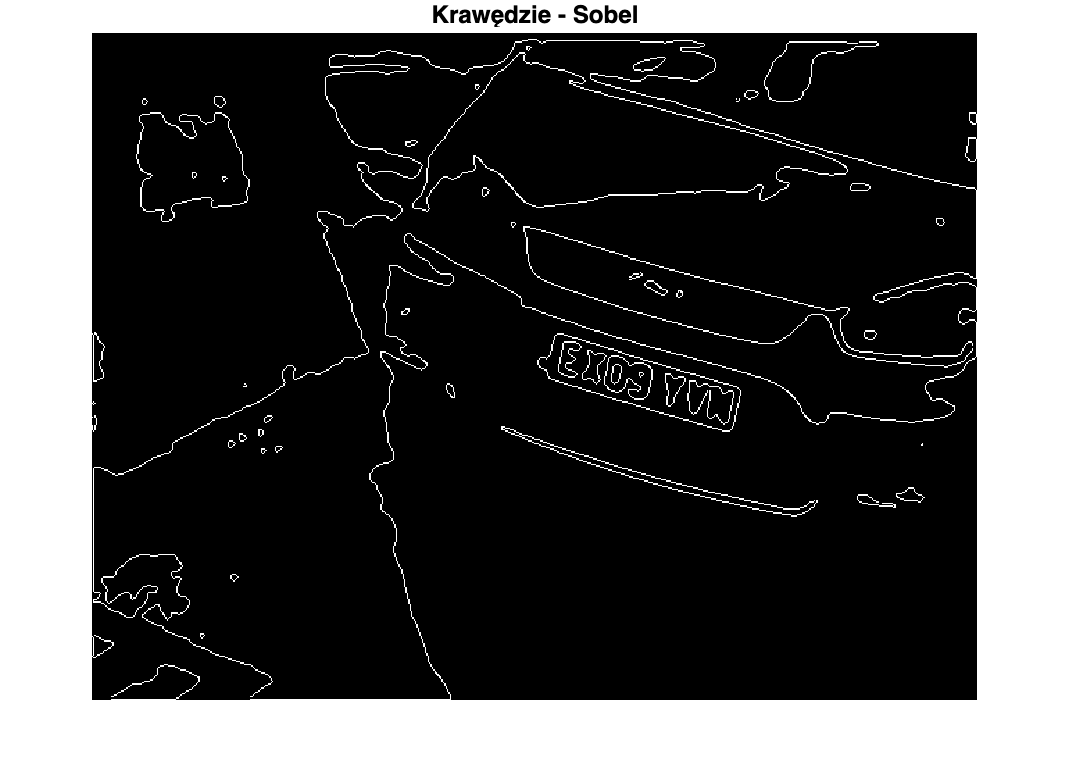


%B1 = imfill(B1, 'holes'); % wypełnienie dziur
%figure; imshow(B1, []); title('Po imfill');

%B1 = bwareaopen(B1, 200); % usunięcie obiektów < 200 px
%figure; imshow(B1, []); title('Po bwareaopen (usunięcie małych obiektów)');

% 7. Detekcja krawędzi
% Sobel
Isob = edge(B1, 'sobel');
figure; imshow(Isob, []); title('Krawędzie - Sobel');

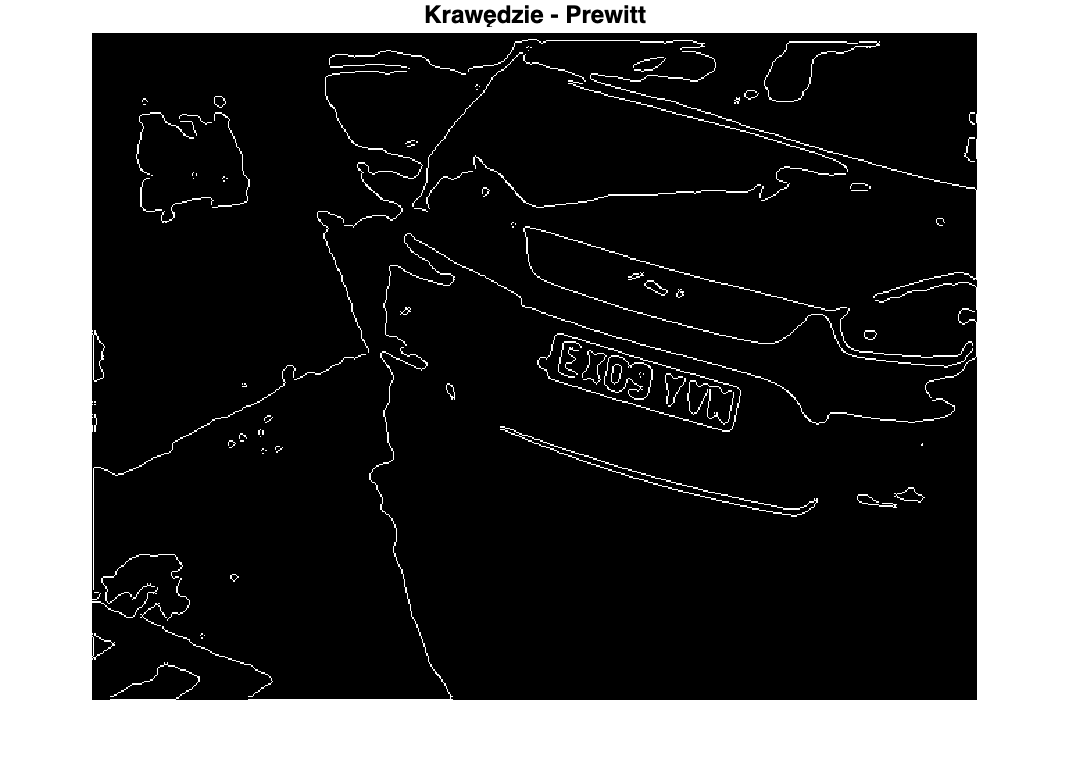


% Prewitt (dla porównania)
Iprew = edge(B1, 'prewitt');
figure; imshow(Iprew, []); title('Krawędzie - Prewitt');

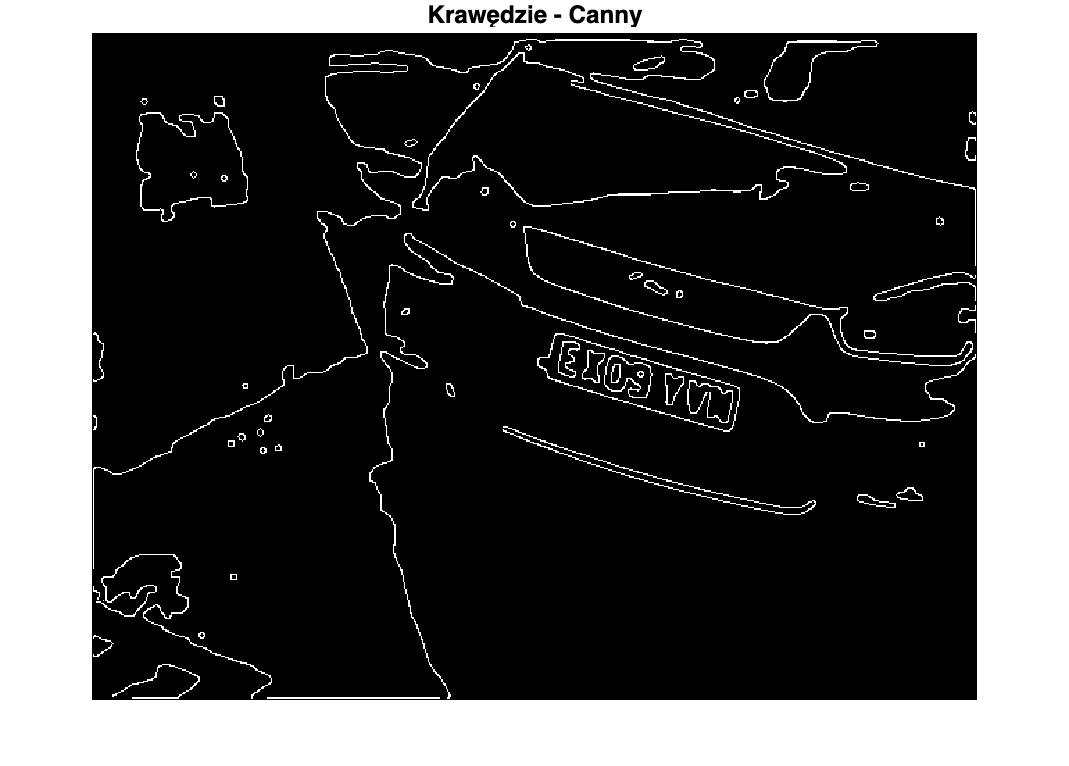


% Canny
Ican = edge(B1, 'canny', [0.1 0.3]); % progi histerezy: 10%, 30%
figure; imshow(Ican, []); title('Krawędzie - Canny');